## Lançamentos de dardos

2.

a)

%n = numero de dardos
%m = numero de alvos
n = 20;
m = 100;
p = n/m;
N = 1e5;
plotcount  = 1;
lancamentos1 = randi(m,n,N);

count = 0;
for k = 1:N
    unique_lanc = unique(lancamentos1(:,k)); 
    if length(unique_lanc) == 20
        count = count + 1; 
    end
end

prob_no_repeats = count / N;

prob_no_repeats

prob_no_repeats = 0.1289

b)

count = 0;
for k = 1:N 
    unique_lanc = unique(lancamentos1(:,k)); 
    if length(unique_lanc) ~= 20
        count = count + 1; 
    end
end

prob_repeats = count/N;
prob_repeats

prob_repeats = 0.8711

c)

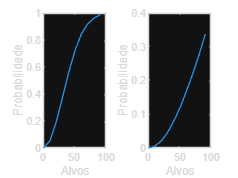

%n = numero de dardos
%m = numero de alvos

N = 1e5;
for m=[1000,10000]
    no_reps = zeros(1,10);
    n_values = zeros(1,10);
    
    i = 1;
    for n = 1:10:100
        n_values(i) = n;
        lancamentos = randi(m,n,N);
        count = 0;
        for k = 1:N 
            unique_lanc = unique(lancamentos(:,k)); 
            if length(unique_lanc) ~= n
                count = count + 1; 
            end
        end
        no_reps(i) = count / N;
        i = i+1;
    end
    subplot(1,2,plotcount);    
    plot(n_values,no_reps);
    ylabel('Probabilidade');
    xlabel('Alvos');
    plotcount = plotcount +1 ;

end   

d)

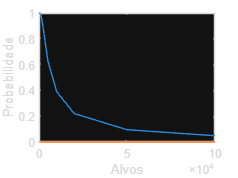

%n = numero de dardos
%m = numero de alvos

N = 1e5;
n = 100;
m = [200,500,1000,2000,5000,10000,20000, 50000, 100000];
no_reps = zeros(length(m));

for k = 1: length(m)
    lancamentos = randi(m(k),n,N);
    count = 0;
    for i = 1:N 
        unique_lanc = unique(lancamentos(:,i)); 
        if length(unique_lanc) <= n-1
            count = count + 1; 
        end
    end
    no_reps(k) = count / N;
end
figure;
plot(m,no_reps);
ylabel('Probabilidade');
xlabel('Alvos');    